% Lista de archivos
files = {'Global_resultados_de_evaluacion.xlsx','Kmeans_resultados_de_evaluacion.xlsx', 'Local_resultados_de_evaluacion.xlsx'};

% Inicializar tabla combinada
allData = table();

% Leer y combinar todas las tablas
for i = 1:length(files)
    T = readtable(files{i});
    allData = [allData; T]; 
end
allData

allData = 162×8 table
         ID_Imagen           Metodo      Verdaderos_Positivos    Falsos_Positivos    Falsos_Negativos    Accuracy_pct    Precision_pct    Recall_pct
    ___________________    __________    ____________________    ________________    ________________    ____________    _____________    __________

    {'20170612_144112'}    {'Global'}             98                    90                  93               26.2            52.13          51.31   
    {'20170709_124326'}    {'Global'}             43                    38                  22               34.4            53.09          66.15   
    {'20170724_145603'}    {'Global'}            269                    11                  72              6


% Mostrar fórmula de la Tasa de FN
fprintf('\n---------------------------------------------------\n');


---------------------------------------------------


fprintf('Cálculo del Promedio de la Tasa de Falsos Negativos (FNR):\n');

Cálculo del Promedio de la Tasa de Falsos Negativos (FNR):


fprintf('Para cada imagen i:\n');

Para cada imagen i:


fprintf('    FNR_i = FN_i / (TP_i + FN_i)\n');

    FNR_i = FN_i / (TP_i + FN_i)


fprintf('Luego, para cada método de segmentación:\n');

Luego, para cada método de segmentación:


fprintf('    FNR_promedio = (1/N) * sum_i [FNR_i] = (1/N) * sum_i [FN_i / (TP_i + FN_i)]\n');

    FNR_promedio = (1/N) * sum_i [FNR_i] = (1/N) * sum_i [FN_i / (TP_i + FN_i)]


fprintf('Se excluyen imágenes donde TP_i + FN_i = 0 para evitar división por cero.\n');

Se excluyen imágenes donde TP_i + FN_i = 0 para evitar división por cero.


fprintf('---------------------------------------------------\n\n');

---------------------------------------------------




% Agrupar por método de segmentación
methods = unique(allData{:,2});
results = table();

% Evaluar cada método
for i = 1:length(methods)
    method = methods{i};
    
    % Filtrar filas del método
    methodData = allData(strcmp(allData{:,2}, method), :);
    
    % Obtener TP y FN
    TP = methodData{:,3};
    FN = methodData{:,4};
    
    % Calcular tasa de falsos negativos por imagen (FN / (TP + FN))
    validIdx = (TP + FN) > 0; 
    FNR = FN(validIdx) ./ (TP(validIdx) + FN(validIdx));
    meanFNR = mean(FNR)*100;  % Promedio de la tasa de FN por imagen

    % Calcular suma total de FN
    totalFN = sum(FN);
    
    % Calcular medias de accuracy, precision y recall
    meanAccuracy = mean(methodData{:,5});
    meanPrecision = mean(methodData{:,6});
    meanRecall = mean(methodData{:,7});
    
    % Guardar resultados
    results = [results; 
        table({method}, meanFNR, totalFN, meanAccuracy, meanPrecision, meanRecall, ...
              'VariableNames', {'Method', 'MeanFNR', 'TotalFN', 'MeanAccuracy', 'MeanPrecision', 'MeanRecall'})];
end

% Ordenar por menor FNR, luego métricas
sortedResults = sortrows(results, {'MeanFNR', 'MeanRecall', 'MeanPrecision', 'MeanAccuracy'}, ...
                                  {'ascend', 'descend', 'descend', 'descend'});

% Mostrar todos los métodos ordenados por FNR
disp('Métodos de segmentación ordenados por tasa promedio de falsos negativos (FNR):');

Métodos de segmentación ordenados por tasa promedio de falsos negativos (FNR):


disp(sortedResults);

      Method       MeanFNR    TotalFN    MeanAccuracy    MeanPrecision    MeanRecall
    ___________    _______    _______    ____________    _____________    __________

    {'Global' }     49.24       1820        42.667           23.144         50.76   
    {'K-means'}     89.19      15667        47.907           8.5754         10.81   
    {'Local'  }    98.674       1997        87.093          0.22426         1.253   




% Mostrar el mejor método
disp('Mejor método de segmentación según el análisis:');

Mejor método de segmentación según el análisis:


disp(sortedResults(1,:));

      Method      MeanFNR    TotalFN    MeanAccuracy    MeanPrecision    MeanRecall
    __________    _______    _______    ____________    _____________    __________

    {'Global'}     49.24      1820         42.667          23.144          50.76   




% Mostrar suma de FN por método
fprintf('\nTotal de falsos negativos (FN) por método:\n');


Total de falsos negativos (FN) por método:


for i = 1:height(results)
    fprintf('   %s: %d FN\n', results.Method{i}, results.TotalFN(i));
end

   Global: 1820 FN
   K-means: 15667 FN
   Local: 1997 FN


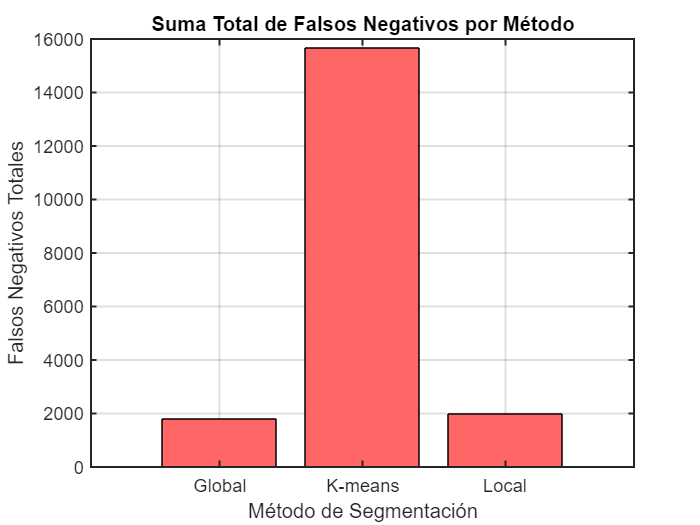


% Suma total de falsos negativos por método
figure;
barColorsFN = [1.0 0.4 0.4]; 

bar(categorical(results.Method), results.TotalFN, 'FaceColor', barColorsFN);
title('Suma Total de Falsos Negativos por Método', 'FontWeight', 'bold', 'FontSize', 14);
ylabel('Falsos Negativos Totales', 'FontSize', 12);
xlabel('Método de Segmentación', 'FontSize', 12);
grid on;
set(gca, 'FontSize', 11, 'LineWidth', 1.2);

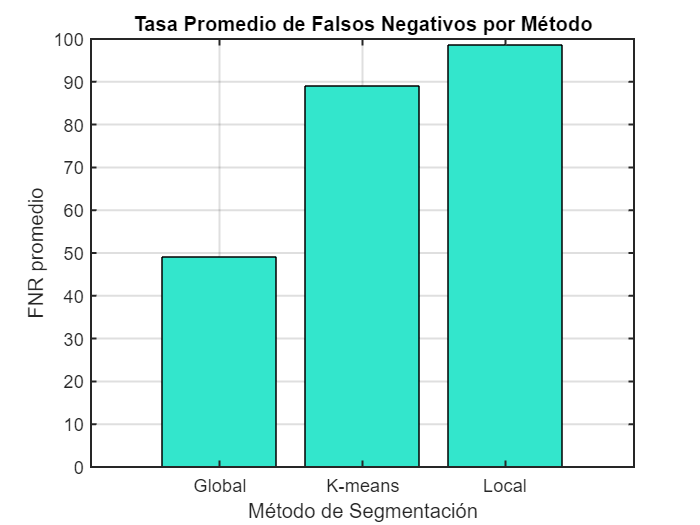


% Tasa de falsos negativos promedio por método
figure;
barColors = [0.2 0.9 0.8]; 
bar(categorical(results.Method), results.MeanFNR, 'FaceColor', barColors);
title('Tasa Promedio de Falsos Negativos por Método', 'FontWeight', 'bold', 'FontSize', 14);
ylabel('FNR promedio', 'FontSize', 12);
xlabel('Método de Segmentación', 'FontSize', 12);
grid on;
set(gca, 'FontSize', 11, 'LineWidth', 1.2);

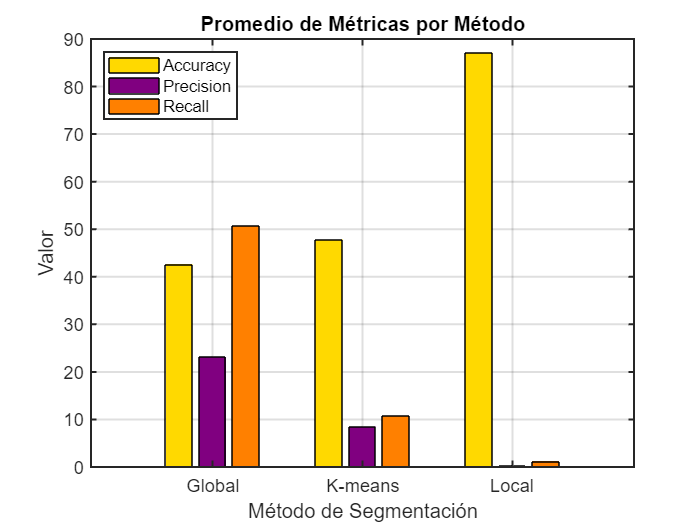


% Métricas promedio por método
figure;
metricsMatrix = [results.MeanAccuracy, results.MeanPrecision, results.MeanRecall];

% Definimos colores para cada barra (accuracy, precision, recall)
colors = [1.0, 0.85, 0.0; 0.5, 0.0, 0.5; 1.0, 0.5, 0.0]; 

b = bar(categorical(results.Method), metricsMatrix);

% Asignar colores personalizados a cada barra
for k = 1:length(b)
    b(k).FaceColor = colors(k,:);
end

title('Promedio de Métricas por Método', 'FontWeight', 'bold', 'FontSize', 14);
ylabel('Valor', 'FontSize', 12);
xlabel('Método de Segmentación', 'FontSize', 12);
legend({'Accuracy', 'Precision', 'Recall'}, 'Location', 'northwest');
grid on;
set(gca, 'FontSize', 11, 'LineWidth', 1.2);